## Prøveeksamen

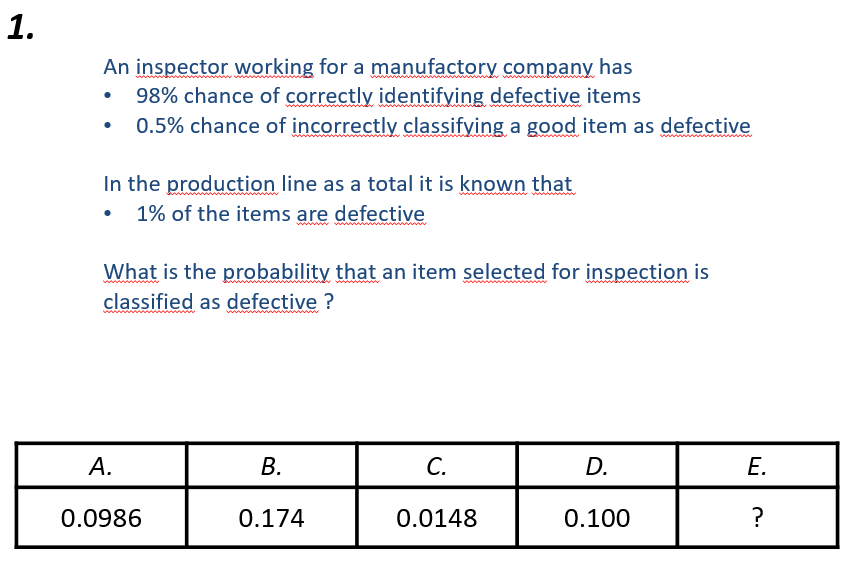

% Total probability rule
% P(B) = P(B|A)*P(A) + P(B|A')*P(A')
% B er, at en defekt identificeres
% A er, at en defekt findes
P_B_A = 0.98;
P_A = 0.01;
P_B_notA = 0.005;
P_notA = 0.99;
P_B = P_B_A * P_A + P_B_notA * P_notA

P_B = 0.0148

Svaret er altså C, 0.0148.

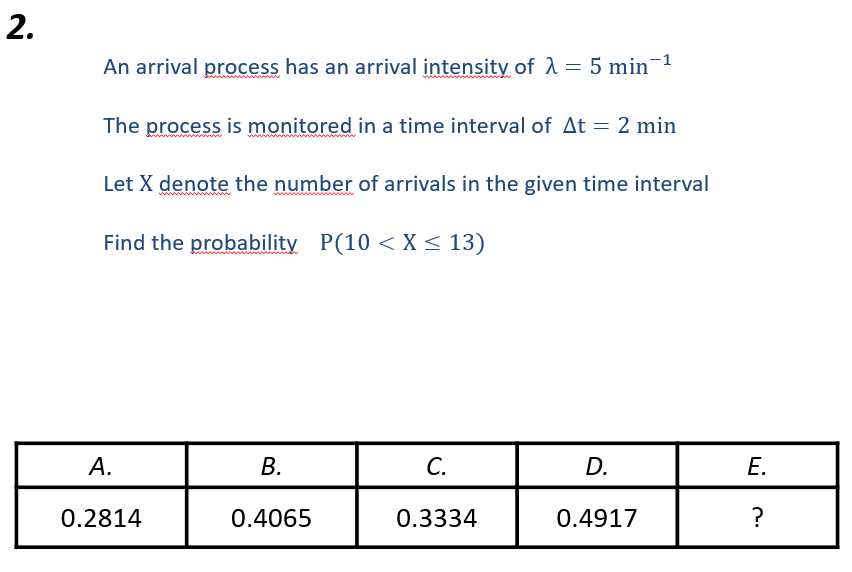

P_11_13 = poisson_prob(5,11,2) + poisson_prob(5,12,2) + poisson_prob(5,13,2)

P_11_13 = 0.2814


%Alternativ:
% P = sum(poisspdf(11:13,2*5))

Svaret er altså A, 0.2814

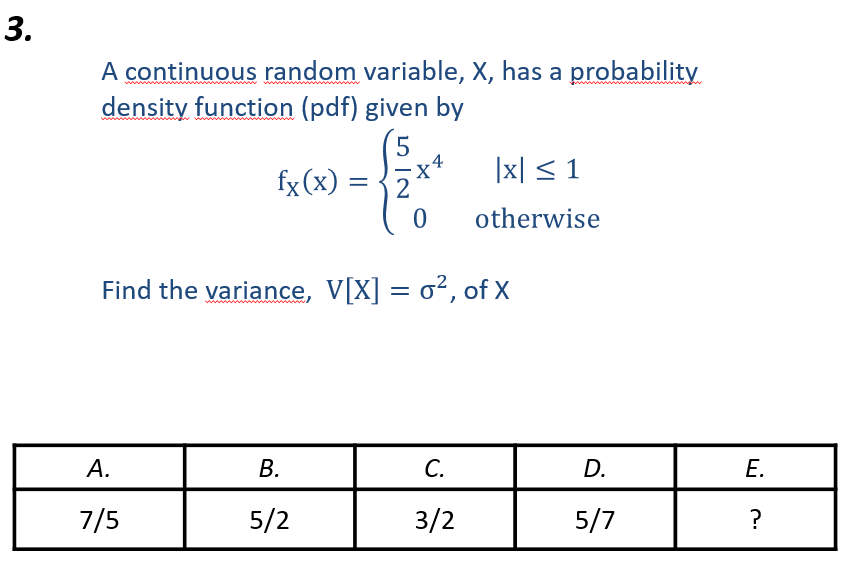

fun = @(x) 5/2 .* x.^5;
mu_x = integral(fun,-1,1)

mu_x = 0


fun2 = @(x) 5/2 .* x.^6;
sigma_x = integral(fun2,-1,1) - mu_x^2

sigma_x = 0.7143

Svaret er altså D, 5/7

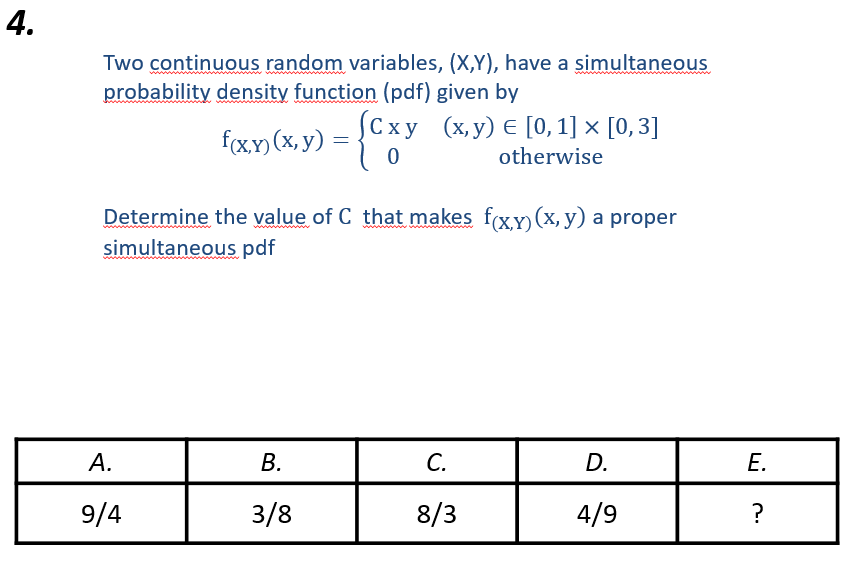

fun = @(x,y) x.*y

fun = function_handle with value:
    @(x,y)x.*y


result = integral2(fun,0,1,0,3)

result = 2.2500

syms C
eq = C * result == 1;
solve(eq,C)

$$ans = \frac{4}{9}$$

Svaret er altså D, 4/9.

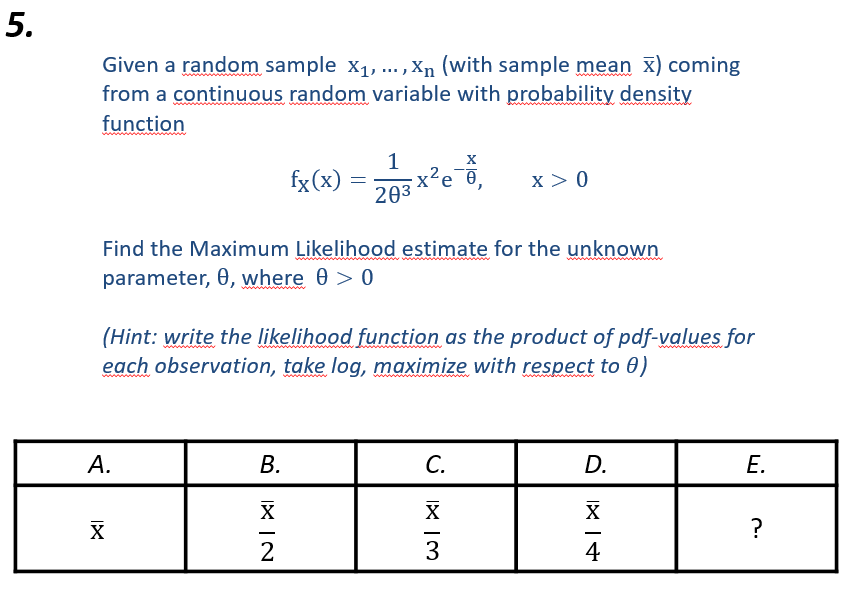

% L(Theta) = f_x(x1) * f_x(x2) * f_x(x3) + ...
% L(Theta) = (2*Theta^3)^-n * e^-(sum(x_i/Theta)) * produkt(x_i^2)
% log L(Theta) = -n*log(2Theta^3) - sum(x_i)/Theta + sum(log(x_i^2))
% dL/dTheta = - n/(2*Theta^3) * 6*Theta^2 + sum(x_i)/Theta^2
% dL/dTheta = 0 ---> 3n/Theta = sum(x_i)/Theta^2
% ---> Theta = sum(x_i)/3n = x_bar / 3

syms x theta
f = 1/(2*theta^3)*x^2*exp(-x/theta);
L = prod(f);
a_hat = solve(diff(log(L),theta)==0,theta)

$$a\_hat = \frac{x}{3}$$

Svaret er altså C, x_bar / 3.

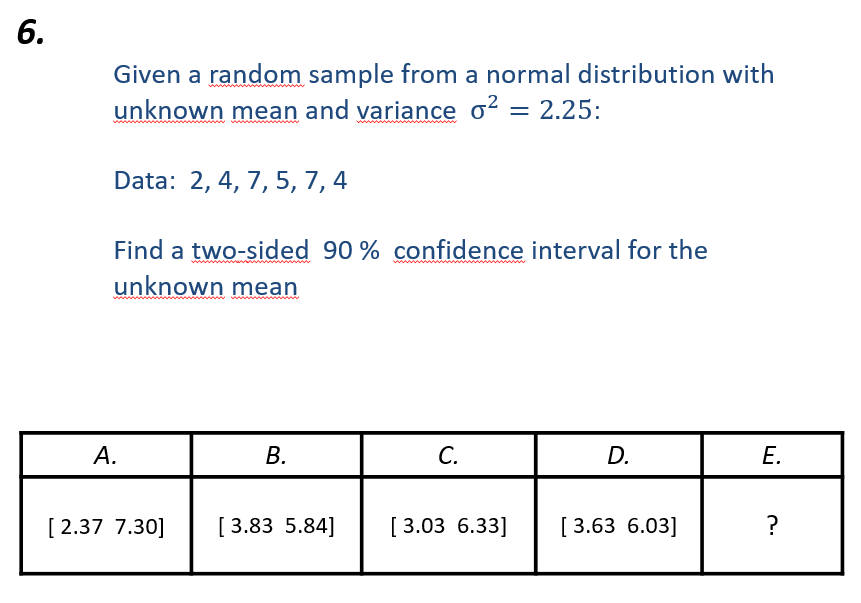

sigma_squared = 2.25

sigma_squared = 2.2500

sigma = sqrt(2.25)

sigma = 1.5000

data = [2 4 7 5 7 4];
n = length(data)

n = 6

mu_x_hat = mean(data)

mu_x_hat = 4.8333


up = mu_x_hat + norminv(1-0.1/2) * sigma/sqrt(n)

up = 5.8406

do = mu_x_hat - norminv(1-0.1/2) * sigma/sqrt(n)

do = 3.8261


% Bedre:
[H, p, CI] = ztest(data,4,sigma,'alpha',0.1);
CI

CI =     3.8261    5.8406


Svaret er altså B, [3.83 5.84].